clear
clc

%% Proving the integral equation matches

gp=0.77;
w=0.1;
d1=0.322;
d2=0.907-0.322;
rect= @(X) 1+(0.52*rectangularPulse(-w/2,w/2,X-(gp/2)));
m=0;

eta1=zeros(1,16);
for lambda=20:35
    Em= @(X) exp(-2*pi*1i*((m*X/gp)+(d1*rect(X)/(lambda/50))))/gp; 
    q=integral(Em,0,gp);
    eta1(lambda-19)=q*conj(q);
end

gp=0.77;
w=0.18;
d1=0.322;
d2=0.907-0.322;
rect= @(X) 1+(0.52*rectangularPulse(-w/2,w/2,X-(gp/2)));
m=0;

eta2=zeros(1,16);
for lambda=20:35
    Em= @(X) exp(-2*pi*1i*((m*X/gp)+(d2*rect(X)/(lambda/50))))/gp; 
    q=integral(Em,0,gp);
    eta2(lambda-19)=q*conj(q);
end

lambda=0.400:0.001:0.700;

A=1.52266;
B=0.000733;
C=-0.0000482;
n_lambda=A+(B*(lambda.^-2))+(C*(lambda.^-4));
gp=0.77;
w1=0.1;
w2=0.18;
D1=w1./gp;
D2=w2./gp;

d1=0.322; %thickness of each layer
d2=0.907-0.322;

dphi1=2*pi./lambda.*d1.*(n_lambda-1);
dphi2=2*pi./lambda.*d2.*(n_lambda-1);

eta1_0=1-(2.*D1)+(2.*D1.^2)+(2.*D1.*(1-D1).*cos(dphi1));
eta2_0=1-(2.*D2)+(2.*D2.^2)+(2.*D2.*(1-D2).*cos(dphi2));
m=3;
eta1_m=4/pi^2/m^2.*(sin(pi.*m.*D1).^2).*(sin(dphi1./2).^2);
eta2_m=4/pi^2/m^2.*(sin(pi.*m.*D2).^2).*(sin(dphi2./2).^2);

figure
hold on
plot(0.4:0.02:0.7,eta1)
xlabel 'wavelength (micrometers)'
ylabel 'intensity (a.u.)'
title 'Diffraction Efficiency'
plot(0.4:0.02:0.7,eta2)
plot(lambda,eta1_0)
plot(lambda,eta2_0)
ylim([0 1])
legend('layer 1 integral method','layer 2 integral method','layer 1 analytical (cos func)','layer 2 analytical (cos func)')
hold off

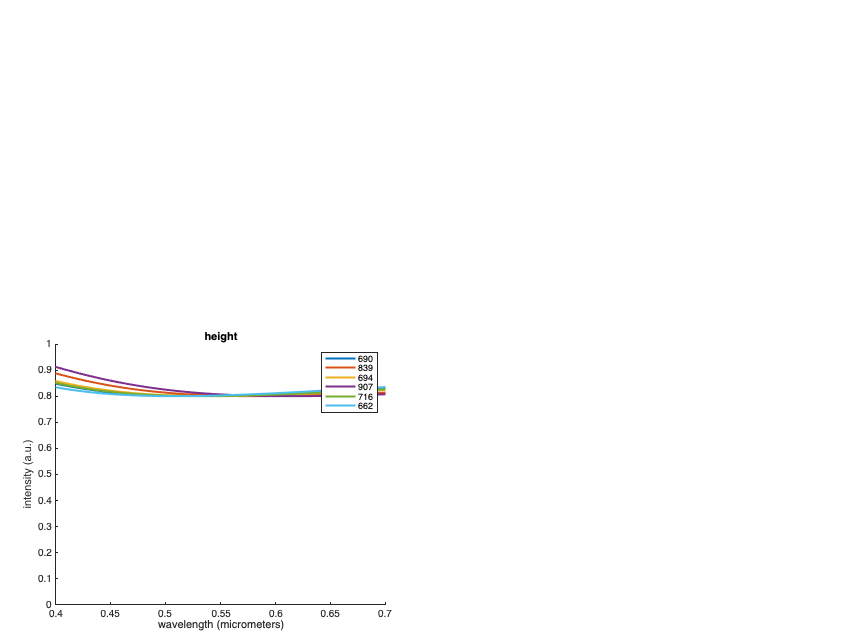

% height model

lambda=0.400:0.001:0.700;

A=1.52266;
B=0.000733;
C=-0.0000482;
n_lambda=A+(B*(lambda.^-2))+(C*(lambda.^-4));
gp=1.07;
w1=0.1;
w2=0.18;
D1=w1./gp;
D2=w2./gp;

d1=[186;283;175;321;207;178]/1000; %thickness of each layer
d2=[691;839;694;907;716;662]/1000;
%d2=d2-d1;

dphi1=2*pi./lambda.*d1.*(n_lambda-1);
dphi2=2*pi./lambda.*d2.*(n_lambda-1);

m=0;
eta1_0=1-(2.*D1)+(2.*D1.^2)+(2.*D1.*(1-D1).*cos(dphi1));
eta2_0=1-(2.*D2)+(2.*D2.^2)+(2.*D2.*(1-D2).*cos(dphi2));

m=1;
eta1_1=4/pi^2/m^2.*(sin(pi.*m.*D1).^2).*(sin(dphi1./2).^2);
eta2_1=4/pi^2/m^2.*(sin(pi.*m.*D2).^2).*(sin(dphi2./2).^2);

m=-1;
eta1_neg1=4/pi^2/m^2.*(sin(pi.*m.*D1).^2).*(sin(dphi1./2).^2);
eta2_neg1=4/pi^2/m^2.*(sin(pi.*m.*D2).^2).*(sin(dphi2./2).^2);

m=2;
eta1_2=4/pi^2/m^2.*(sin(pi.*m.*D1).^2).*(sin(dphi1./2).^2);
eta2_2=4/pi^2/m^2.*(sin(pi.*m.*D2).^2).*(sin(dphi2./2).^2);

m=-2;
eta1_neg2=4/pi^2/m^2.*(sin(pi.*m.*D1).^2).*(sin(dphi1./2).^2);
eta2_neg2=4/pi^2/m^2.*(sin(pi.*m.*D2).^2).*(sin(dphi2./2).^2);

eta_total=eta2_0+eta2_1+eta2_neg1; %+eta2_2+eta2_neg2;

figure
for i=1:6
    hold on
    plot(lambda,eta_total(i,:),'LineWidth',2)
end
hold off
%ylim([0 1])
xlabel 'wavelength (micrometers)'
ylabel 'intensity (a.u.)'
title 'height'
legend('690','839','694','907','716','662')

% grating pitch model

lambda=0.400:0.001:0.700;

A=1.52266;
B=0.000733;
C=-0.0000482;
n_lambda=A+(B*(lambda.^-2))+(C*(lambda.^-4));
gp=[0.7;0.8;0.9;1];
w1=0.1;
w2=0.18;
D1=w1./gp;
D2=w2./gp;

d1=0.322; %thickness of each layer
d2=0.907-0.322;

dphi1=2*pi./lambda.*d1.*(n_lambda-1);
dphi2=2*pi./lambda.*d2.*(n_lambda-1);

m=0;
eta1_0=1-(2.*D1)+(2.*D1.^2)+(2.*D1.*(1-D1).*cos(dphi1));
eta2_0gp=1-(2.*D2)+(2.*D2.^2)+(2.*D2.*(1-D2).*cos(dphi2));

m=1;
eta1_1=4/pi^2/m^2.*(sin(pi.*m.*D1).^2).*(sin(dphi1./2).^2);
eta2_1gp=4/pi^2/m^2.*(sin(pi.*m.*D2).^2).*(sin(dphi2./2).^2);

m=-1;
eta1_neg1=4/pi^2/m^2.*(sin(pi.*m.*D1).^2).*(sin(dphi1./2).^2);
eta2_neg1gp=4/pi^2/m^2.*(sin(pi.*m.*D2).^2).*(sin(dphi2./2).^2);

m=2;
eta1_2=4/pi^2/m^2.*(sin(pi.*m.*D1).^2).*(sin(dphi1./2).^2);
eta2_2gp=4/pi^2/m^2.*(sin(pi.*m.*D2).^2).*(sin(dphi2./2).^2);

m=-2;
eta1_neg2gp=4/pi^2/m^2.*(sin(pi.*m.*D1).^2).*(sin(dphi1./2).^2);
eta2_neg2gp=4/pi^2/m^2.*(sin(pi.*m.*D2).^2).*(sin(dphi2./2).^2);

eta_totalgp=eta2_0gp+eta2_1gp+eta2_neg1gp+eta2_2gp+eta2_neg2gp;

figure
hold on
for i=1:4
    plot(lambda,eta_totalgp(i,:),'LineWidth',2)
end
hold off
%ylim([0 1])
xlabel 'wavelength (micrometers)'
ylabel 'intensity (a.u.)'
title 'grating pitch'
legend('770','870','970','1070')